clc;close all;clear;

## `spatial domain filtering`

house = imread('E:\DSP\DSP_CA4\DSP - Final Project\data\house.jpg');
kSharpen = [0 -1 0;-1 5 -1;0 -1 0];
kBlur = [1/16 1/8 1/16;1/8 1/4 1/8;1/16 1/8 1/16];
kOutline = [-1 -1 -1;-1 8 -1;-1 -1 -1];
kGauss = [.0113 0.0838 0.0113;0.0838 0.8193 0.0838;0.0113 0.1111 0.0113];
KAvgmoving = [0.1111 0.1111 0.1111;0.1111 0.1111 0.1111;0.1111 0.1111 0.1111];
kLineh = [-1 -1 -1;2 2 2;-1 -1 -1];
kLinev = [-1 2 -1;-1 2 -1;-1 2 -1];
kIdentity = [0 0 0;0 1 0;0 0 0];

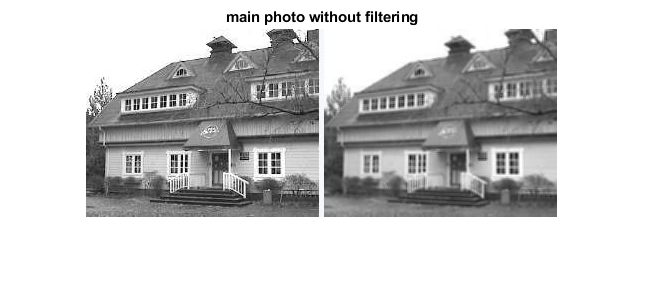

house_sharp = imfilter(house,kSharpen);
house_blur = imfilter(house,kBlur);
house_outline = imfilter(house,kOutline);
house_gauss = imfilter(house,kGauss);
house_avgmoving = imfilter(house,KAvgmoving);
house_lineh = imfilter(house,kLineh);
house_linev = imfilter(house,kLinev);
house_identity = imfilter(house,kIdentity);
imshow(house);
title('main photo without filtering');

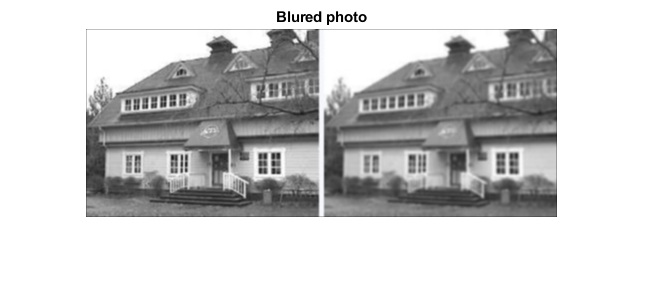

imshow(house_blur);
title('Blured photo');

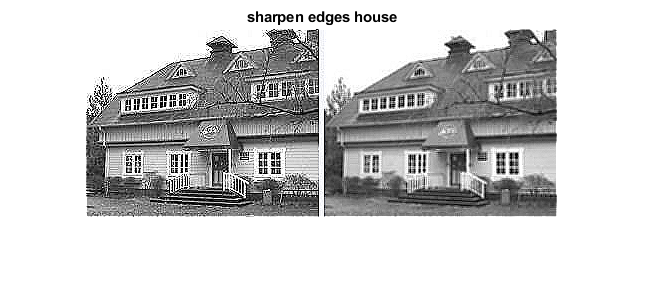

imshow(house_sharp);
title('sharpen edges house');

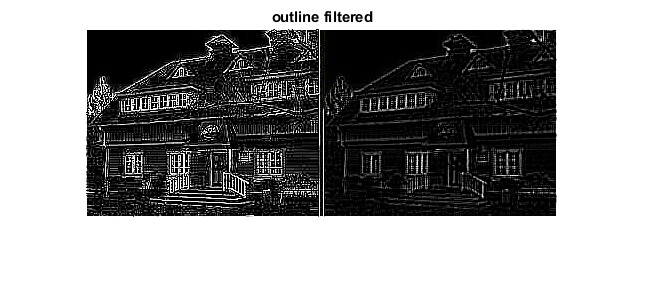

imshow(house_outline);
title('outline filtered');

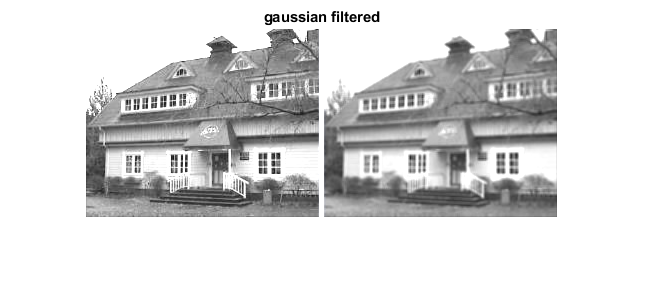

imshow(house_gauss);
title('gaussian filtered');

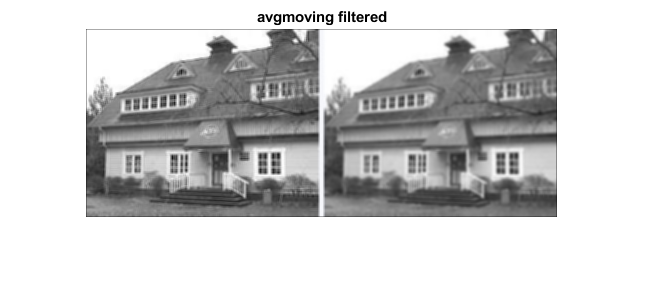

imshow(house_avgmoving);
title('avgmoving filtered');

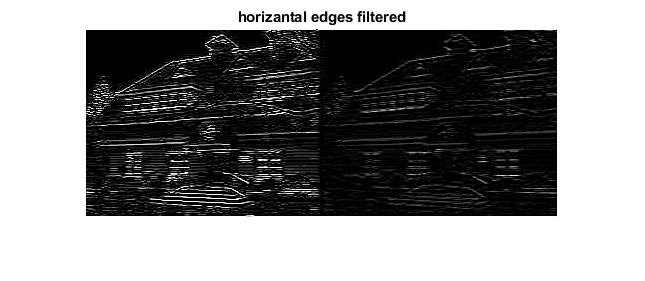

imshow(house_lineh);
title('horizantal edges filtered');

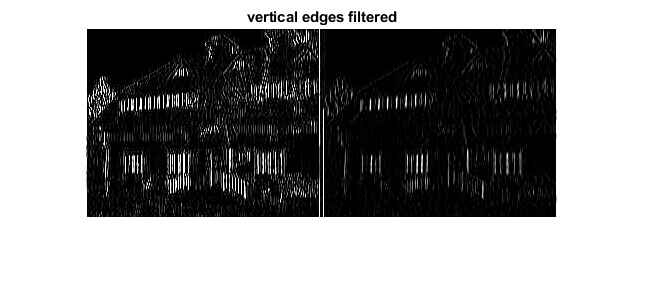

imshow(house_linev);
title('vertical edges filtered');

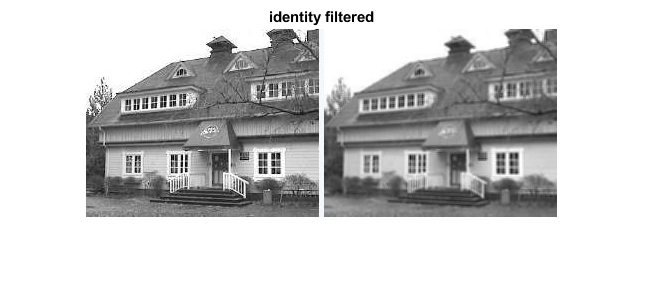

imshow(house_identity);
title('identity filtered');

kobe = imread('E:\DSP\DSP_CA4\DSP - Final Project\data\kobe.jpeg');
imshow(kobe);

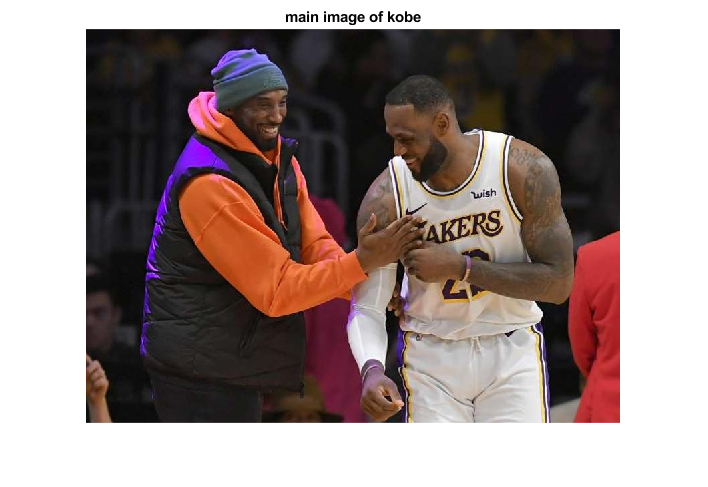

title('main image of kobe');

onefifthkobe = imresize(kobe , 1/5);
recons_kobe = imresize(onefifthkobe,5,'nearest');
figure
imshow(recons_kobe);

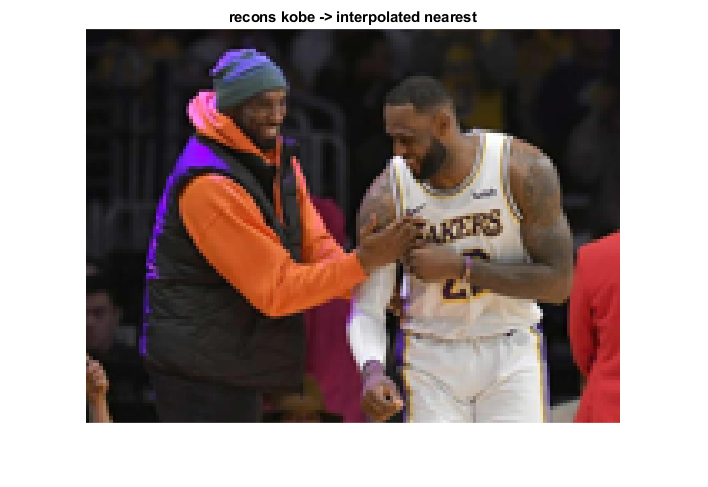

title('recons kobe -> interpolated nearest');

avg_recons_kobe = imfilter(recons_kobe,KAvgmoving);
gauss_recons_kobe = imfilter(recons_kobe,kGauss);
figure
imshow(avg_recons_kobe);

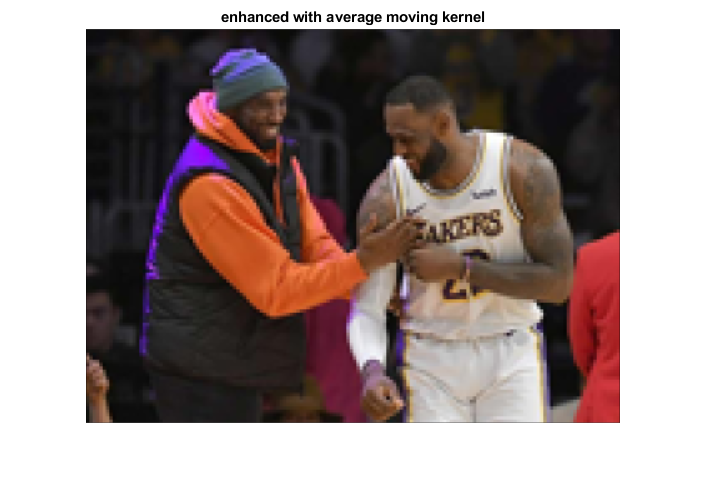

title('enhanced with average moving kernel');

figure
imshow(gauss_recons_kobe);

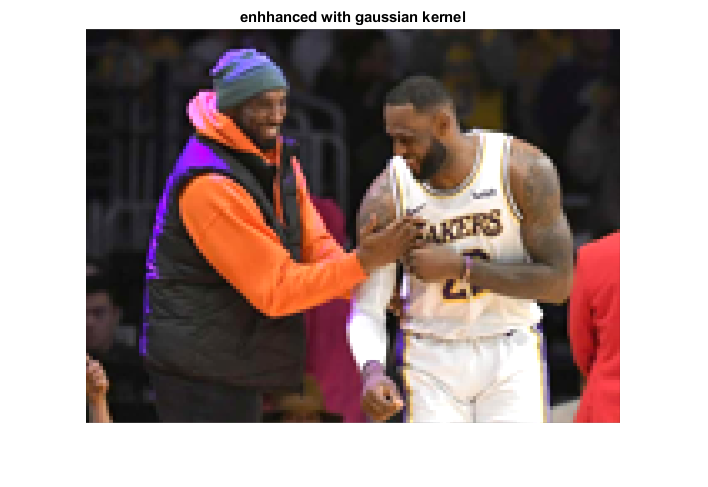

title('enhhanced with gaussian kernel');

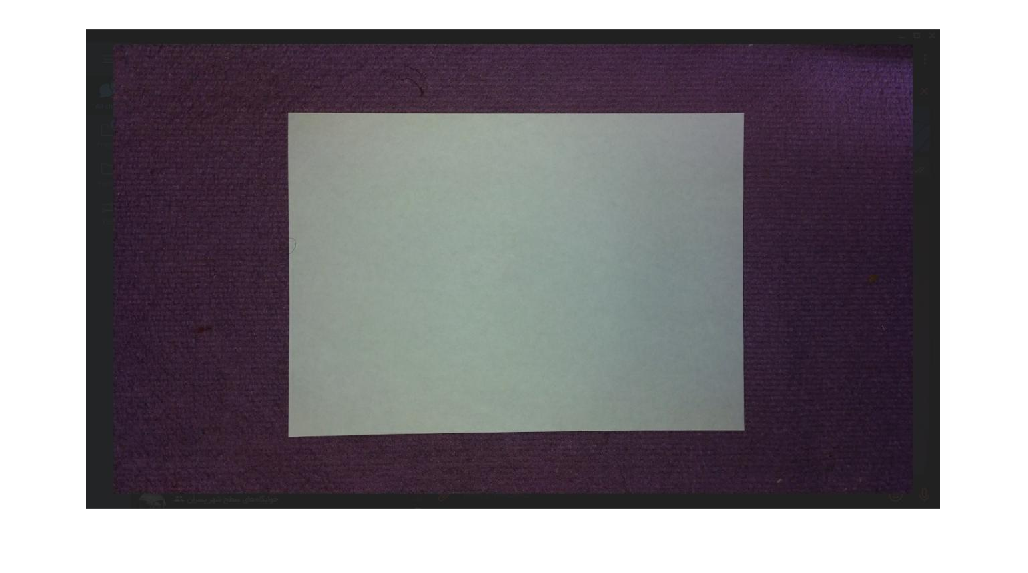

page = imread('E:\DSP\DSP_CA4\DSP - Final Project\data\page3.jpg');
gray_page = rgb2gray(page);
figure
imshow(page);

vedge_page = imfilter(gray_page,kLinev,'full');
hedge_page = imfilter(gray_page,kLineh,'full');
figure
imshow(vedge_page);

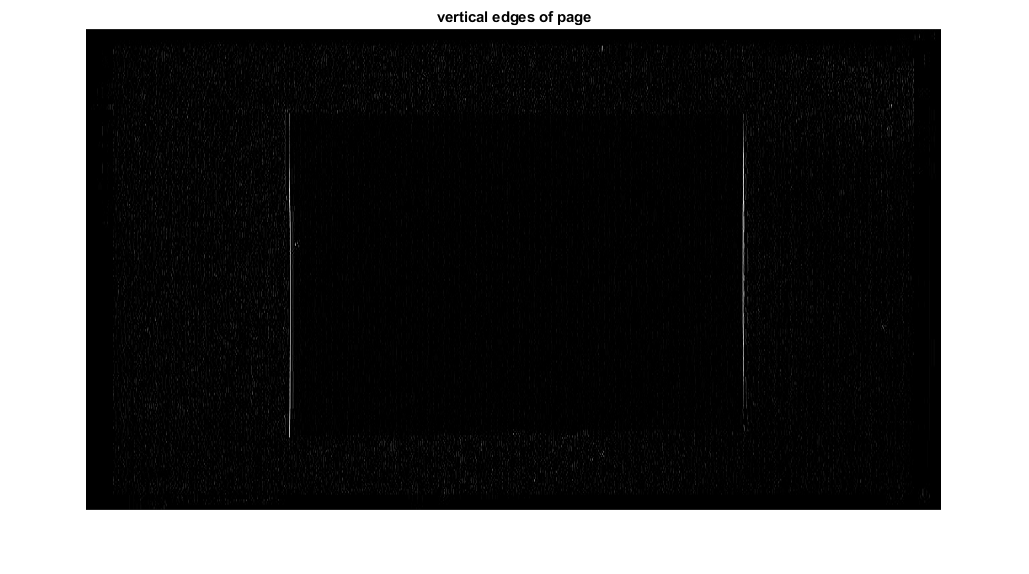

imwrite(wiener2(vedge_page,[5 5]),'verticaledgepage.jpg');
title('vertical edges of page');

figure
imshow(hedge_page);

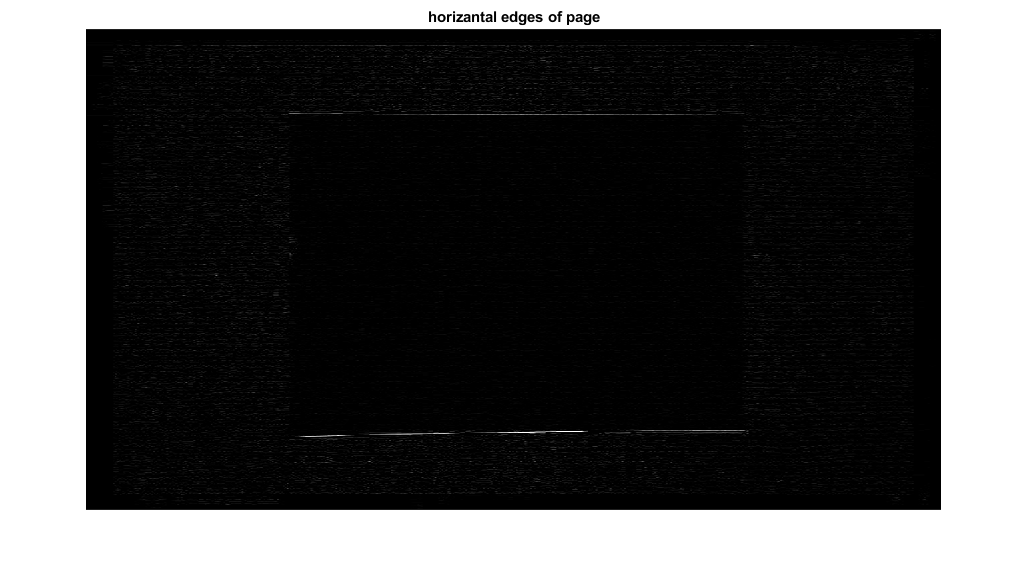

imwrite(wiener2(hedge_page,[5 5]),'horizantaledgepage.jpg');
 title('horizantal edges of page');

test =vedge_page;
test2 = sum((test>128),1);
smooth_vertical_sum = smooth(smooth(test2));
smooth_vertical_sum(smooth_vertical_sum<10)=0;
en_svs = smooth_vertical_sum(30:length(smooth_vertical_sum)-30);
[vpks,vloc]=findpeaks(en_svs);
test2(test2<20)=0

test2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[~,mainlocv]=findpeaks(test2);
lv = length(vloc);
nvloc = zeros(lv+2,1);
nvloc(1)=0;
nvloc(lv+2)=0;
for i=2:lv+1
    nvloc(i)=vloc(i-1);
end
for i=1:lv+1
    if(abs(nvloc(i)-nvloc(i+1))<35)
        nvloc(i)=max(nvloc(i),nvloc(i+1));
        nvloc(i+1)=0;
    end
end

ver = hedge_page;
ver2 = sum((ver>128),2);
smooth_hor_sum = smooth(smooth(ver2));
smooth_hor_sum(smooth_hor_sum<10)=0;
en_shs = smooth_hor_sum(30:length(smooth_hor_sum)-30);
[hpks,hloc]=findpeaks(en_shs);
ver2(ver2<20)=0

ver2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


[~,mainloch]=findpeaks(ver2);


hv = length(hloc);
hvloc = zeros(hv+2,1);
hvloc(1)=0;
hvloc(hv+2)=0;
for i=2:hv+1
    hvloc(i)=hloc(i-1);
end
for i=1:hv+1
    if(abs(hvloc(i)-hvloc(i+1))<35)
        hvloc(i)=max(hvloc(i),hvloc(i+1));
        hvloc(i+1)=0;
    end
end
hvloc(hvloc==0)=[];
nvloc(nvloc==0)=[];
hvloc1=maxk(hvloc,2);
nvloc1=maxk(nvloc,2);
width = nvloc(2)-nvloc(1);
len = hvloc(2)-hvloc(1);


for i=1:length(mainloch)
    for j=1:2
        if((abs(mainloch(i)-hvloc(j))<70))
            hvloc(j)=mainloch(i);
        end
    end
end
for i=1:length(mainlocv)
    for j=1:2
        if((abs(mainlocv(i)-nvloc(j))<70))
            nvloc(j)=mainlocv(i);
        end
    end
end

figure
imshow(page);

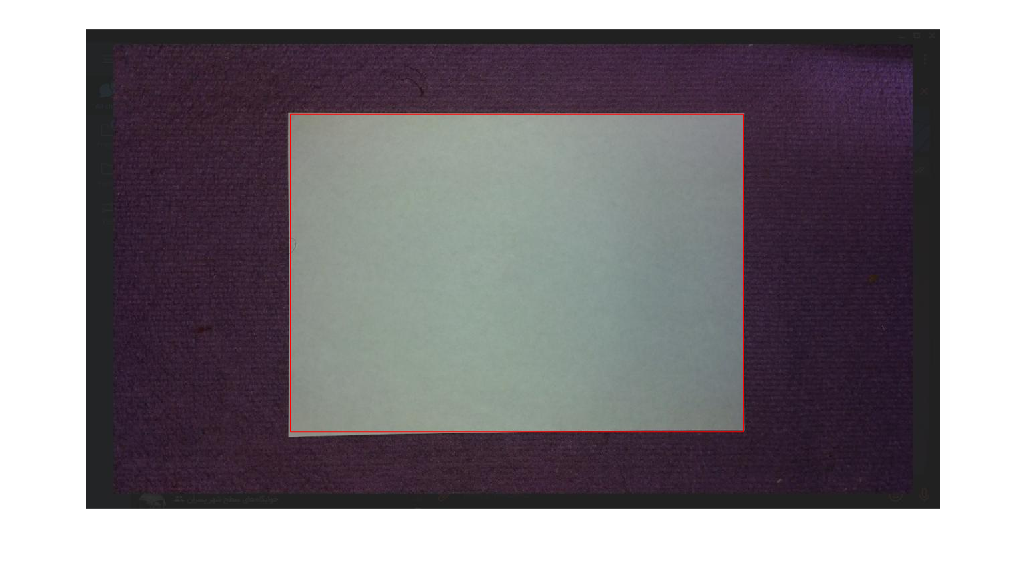

hold on;
rectangle('position',[nvloc(1),hvloc(1),width,len],'EdgeColor','r');

**frequency domain filtering**

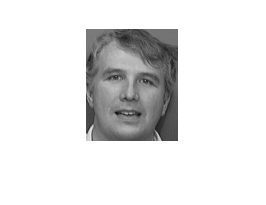


p1_1 = imread('E:\DSP\DSP_CA4\DSP - Final Project\data\att-database-of-faces\s15\7.pgm');
figure
imshow(p1_1);

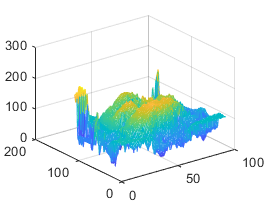

mesh(p1_1);

%m_p1_1 = abs(p1_1);
%p_p1_1 = angle(p1_1);
fft2_p1_1 = fft2(p1_1);
fftsh_p1_1=fftshift(fft2_p1_1);
imshow(uint8(ifft2(ifftshift(fftsh_p1_1))));

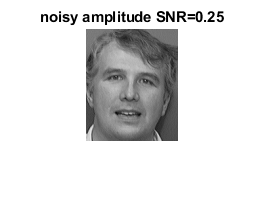

m_p1_1 = abs(fftsh_p1_1);
a_p1_1 = angle(fftsh_p1_1);

a_noisy_p1_1_25 = awgn(angle(fftsh_p1_1),.25);
a_noisy_p1_1_50 = awgn(angle(fftsh_p1_1),.50);
a_noisy_p1_1_100 = awgn(angle(fftsh_p1_1),1);

m_noisy_p1_1_25 = awgn(abs(fftsh_p1_1),0.25);
m_noisy_p1_1_50 = awgn(abs(fftsh_p1_1),.50);
m_noisy_p1_1_100 = awgn(abs(fftsh_p1_1),1);

tmfa_25=m_p1_1.*exp(j*a_noisy_p1_1_25);
tmfa_50=m_p1_1.*exp(j*a_noisy_p1_1_50);
tmfa_100=m_p1_1.*exp(j*a_noisy_p1_1_100);

fmta_25=m_noisy_p1_1_25.*exp(j*a_p1_1);
fmta_50=m_noisy_p1_1_50.*exp(j*a_p1_1);
fmta_100=m_noisy_p1_1_100.*exp(j*a_p1_1);

noisy_amp_25 = ifft2(ifftshift(fmta_25));
noisy_amp_50 = ifft2(ifftshift(fmta_50));
noisy_amp_100 = ifft2(ifftshift(fmta_100));

noisy_phs_25 = ifft2(ifftshift(tmfa_25));
noisy_phs_50 = ifft2(ifftshift(tmfa_50));
noisy_phs_100 = ifft2(ifftshift(tmfa_100));
figure
imshow(uint8(abs(noisy_amp_25)));
title('noisy amplitude SNR=0.25');

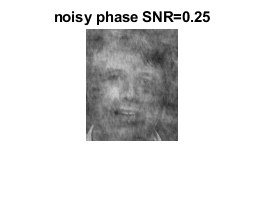

figure
imshow(uint8(abs(noisy_phs_25)));
title('noisy phase SNR=0.25');

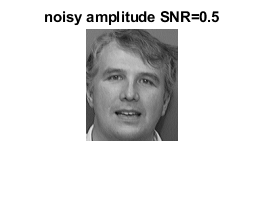

figure
imshow(uint8(abs(noisy_amp_50)));
title('noisy amplitude SNR=0.5');

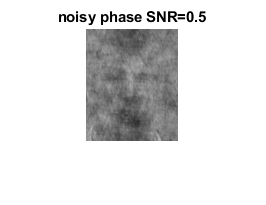

figure
imshow(uint8(abs(noisy_phs_50)));
title('noisy phase SNR=0.5');

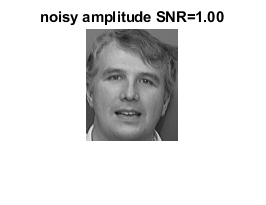

figure
imshow(uint8(abs(noisy_amp_100)));
title('noisy amplitude SNR=1.00');

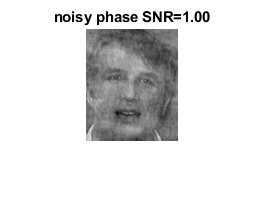

figure
imshow(uint8(abs(noisy_phs_100)));
title('noisy phase SNR=1.00');

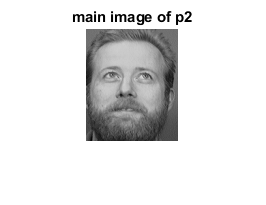



p2 = imread('E:\DSP\DSP_CA4\DSP - Final Project\data\att-database-of-faces\s26\7.pgm');
p3 = imread('E:\DSP\DSP_CA4\DSP - Final Project\data\att-database-of-faces\s33\7.pgm');
fft_p2 = fftshift(fft2(p2));
fft_p3 = fftshift(fft2(p3));

amp_p2 = abs(fft_p2);
phs_p2 = angle(fft_p2);

amp_p3 = abs(fft_p3);
phs_p3 = angle(fft_p3);

amp_p2_phase_p3 = amp_p2.*exp(j*phs_p3);
amp_p3_phase_p2 = amp_p3.*exp(j*phs_p2);

a2p3 = ifft2(ifftshift(amp_p2_phase_p3));
a3p2 = ifft2(ifftshift(amp_p3_phase_p2));

imshow(p2);
title('main image of p2')

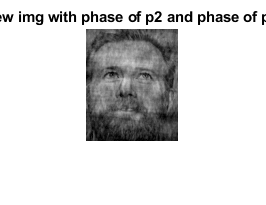

imshow(uint8(abs(a3p2)));
title('new img with phase of p2 and phase of p3')

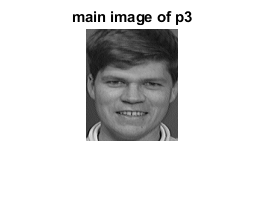


imshow(p3);
title('main image of p3')

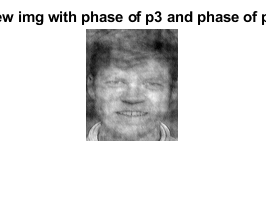

imshow(uint8(abs(a2p3)));
title('new img with phase of p3 and phase of p2')

**Face recognition**

% allData = cell(40, 10);
% add_dir = dir('E:\DSP\DSP_CA4\DSP - Final Project\data\att-database-of-faces\*\*.pgm');
% for i = 1:40
%     for j=1:10
%     allData(i,j) = {imread(fullfile(add_dir(i).folder, add_dir(j).name))};
%     end
% end
str = dir('E:\DSP\DSP_CA4\DSP - Final Project\data\att-database-of-faces\*\*.pgm');
for i = 1:10
    for j=1:40
    add = "E:\DSP\DSP_CA4\DSP - Final Project\data\att-database-of-faces\s"+num2str(j)+"\"+num2str(i)+".pgm";
    allData(j,i) = {imread(char(add))};
    end
end



Train_Autoencodering_Data = trainAutoencoder(allData(:, 1:8), 100, 'MaxEpochs', 1000,'UseGPU',true);

Cannot perform computations on a GPU.
No GPU available.


predicted_img=cell(40, 2);
predict_acc=cell(40,2);
for i=1:40
    for j=1:2
        predicted_img(i,j) = predict(Train_Autoencodering_Data,allData(i,8+j));

    end
end
for i=1:40
    for j=1:2
        predict_acc(i,j) = predict(Train_Autoencodering_Data,allData(i,j));

    end
end

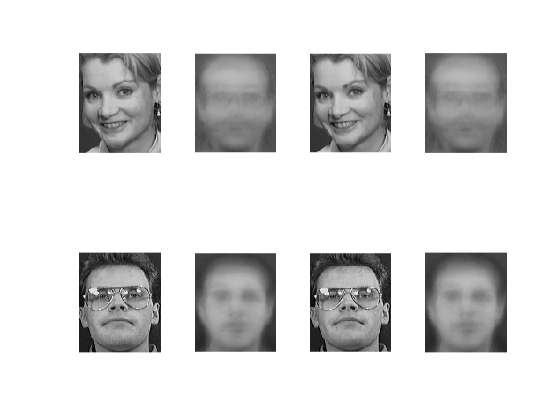

figure
title('not mentioned data in learning')
for i=1:4
    a=(i>2);
    subplot(2,4,2*i-1)
    imshow(allData{35+a,9+a})
    subplot(2,4,2*i)
    imshow(uint8(predicted_img{35+a,a+1}))
end

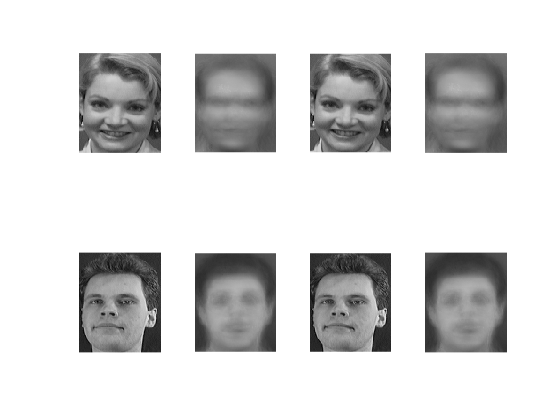


figure
title('mentioned data in learning')
for i=1:4
    a=(i>2);
    subplot(2,4,2*i-1)
    imshow(allData{35+a,1+a})
    subplot(2,4,2*i)
    imshow(uint8(predict_acc{35+a,a+1}))
end


Encoded_Trained_Data= encode(Train_Autoencodering_Data, allData(:,1:8)); 
Train_Soft_max_Layer = trainSoftmaxLayer(Encoded_Trained_Data, repmat(eye(40), 1, 8));
Stacked_SFML_AED = stack(Train_Autoencodering_Data, Train_Soft_max_Layer);
Testing_Data = zeros(length(allData{1}(:)), 400);

for i = 1:400
    Testing_Data(:, i) = allData{i}(:);
end
eye_m=eye(40);
LastPart= zeros(40, 400);
Regretice_Data = Stacked_SFML_AED(Testing_Data);
for i = 1:400
    for j = 1:40
        LastPart(j, i) = norm(Regretice_Data(:, i)-eye_m(:, j));
    end
end

[~, I] = min(LastPart);
TotalAccuracy = sum(I == repmat(1:40, 1, 10))/400*100

TotalAccuracy = 98.2500

TrainDataAccuracy = sum(I(1:320) == repmat(1:40, 1, 8))/320*100

TrainDataAccuracy = 100

TestDAtaAccuracy = sum(I(321:400) == repmat(1:40, 1, 2))/80*100

TestDAtaAccuracy = 91.2500